# SRP contour plot

## ref.

polarplot3dをMATLAB file exchangeからダウンロードする必要あり

clc
clear
cls

format long

## satelltie configuration

nFacet = 1;
sat.pos = [0 0 0];
sat.normal = [0 0 1];
sat.area = 1;

testCase = 1

testCase =      1



sat.mCT = 0.1;
sat.nu = 100; % 100 or 800
sat.nv = 50;
sat.F0 = 0.5 .* ones(nFacet, 1);
sat.rho = 0.5 .* ones(nFacet, 1);

## parameters

const = orbitConst;
d = au2km(1.0, const) * 10^3; % m, distance from sat to sun
dAU = km2AU(d ./ 10^3, const); % AU
S0 = const.S0; % Solar constant, W/m^2
c = const.c; % light speed, m/s
coeff = -S0 / c / dAU^2;

## specular

sun vector (from satellite to Sun): ${\bf s} = [\cos\phi_i \sin\theta_i, \sin\phi_i, \sin\theta_i, \cos\theta_i]^T$

phiIrange = deg2rad(0):deg2rad(5):deg2rad(360);
thetaIrange = 0:deg2rad(3):deg2rad(89);
[phiI, thetaI] = meshgrid(phiIrange, thetaIrange);

% pre-allocation
srpCsTrueX = zeros(size(phiI));
srpCsTrueY = zeros(size(phiI));
srpCsTrueZ = zeros(size(phiI));
srpCsApproxX = zeros(size(phiI));
srpCsApproxY = zeros(size(phiI));
srpCsApproxZ = zeros(size(phiI));


for i = 1:size(phiI,1)
    for j = 1:size(phiI, 2)
        phi = phiI(i,j);
        theta = thetaI(i,j);
        sunB = [sin(theta)*cos(phi), sin(theta)*sin(phi), cos(theta)];
        NS = sat.normal * sunB';
        sunlitFlag = (sat.normal * sunB' > 0); % nFacetx1 matrix, 1: sunlit, 0: shade

### true (numerically)

                [sat, ~, tmp] = srpAS(sat, sunB, d, const, 10^5);
%         [sat, ~, tmp] = srpCT(sat, sunB, d, const);
        srpCsTrueX(i,j) = tmp(1) / abs(coeff);
        srpCsTrueY(i,j) = tmp(2) / abs(coeff);
        srpCsTrueZ(i,j) = tmp(3) / abs(coeff);

    end
end


## show figures

### color range

% adaptive range
cxRange = [min(srpCsTrueX, [], 'all') max(srpCsTrueX, [], 'all')]

cxRange =   -0.215055887657987   0.220597233125872


cyRange = [min(srpCsTrueY, [], 'all') max(srpCsTrueY, [], 'all')]

cyRange =   -0.203639239516928   0.205557939471394


czRange = [min(srpCsTrueZ, [], 'all') max(srpCsTrueZ, [], 'all')]

czRange =   -0.456051318536352  -0.003539632169814



% fixed range
% cxRange = [-0.1e-5 0.1e-5];
% cyRange = [-1e-6 1e-6];
% czRange = [-0.25e-5 0];

### contour

% figure
% subplot(1,2,1)
% [~, cTrueX] = contourf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsTrueX, 10);
% colorbar
% clim([-1e-6 1e-6])
% axis equal
% view([0 90])
% subplot(1,2,2)
% [~, cApproxX] =contourf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsApproxX);
% set(cApproxX, 'LevelList' ,cTrueX.LevelList);
% colorbar
% clim([-1e-6 1e-6])
% % title('absolute error')
% axis equal
% xlabel('x'), ylabel('y')
% view([0 90])
%
% figure
% subplot(1,2,1)
% [~, cTrueY] = contourf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsTrueY, 10);
% colorbar
% clim([-1e-6 1e-6])
% axis equal
% view([0 90])
% subplot(1,2,2)
% [~, cApproxY] = contourf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsApproxY);
% set(cApproxY, 'LevelList' ,cTrueY.LevelList);
% colorbar
% clim([-1e-6 1e-6])
% % title('absolute error')
% axis equal
% xlabel('x'), ylabel('y')
% view([0 90])
%
% figure
% subplot(1,2,1)
% [~, cTrueZ] = contourf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsTrueZ, 10);
% colorbar
% clim([-2.5e-6 0])
% axis equal
% view([0 90])
% subplot(1,2,2)
% [~, cApproxZ] = contourf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsApproxZ);
% set(cApproxZ, 'LevelList' ,cTrueZ.LevelList, 'lineStyle','--');
% colorbar
% clim([-2.5e-6 0])
% % title('absolute error')
% axis equal
% xlabel('x'), ylabel('y')
% view([0 90])


## Surf

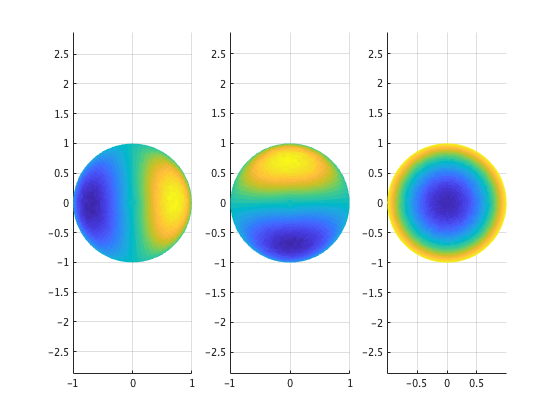

figure
subplot(1,3,1)
surf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsTrueX, EdgeColor = 'none')
view([0 90])
clim(cxRange)
axis equal

subplot(1,3,2)
surf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsTrueY, EdgeColor = 'none')
view([0 90])
clim(cyRange)
axis equal

subplot(1,3,3)
surf(cos(phiI).*sin(thetaI), sin(phiI).*sin(thetaI), srpCsTrueZ, EdgeColor = 'none')
view([0 90])
clim(czRange)
axis equal

### Polar plot

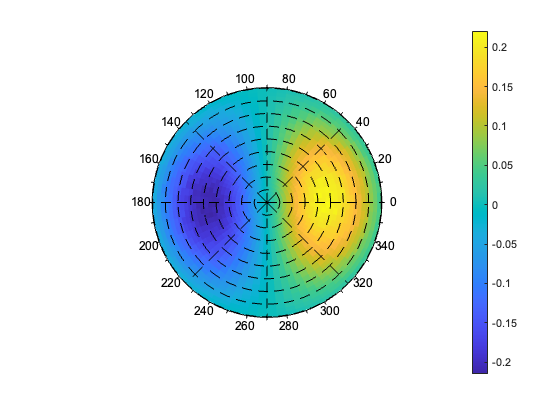


figure
polarplot3d(srpCsTrueX, 'GridStyle', '--', 'PolarGrid', {9 8}, 'PlotType', 'surfn');
view([0 90]); axis equal
clim(cxRange)

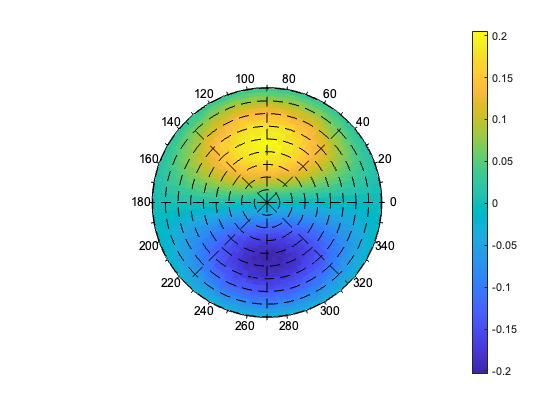


figure
polarplot3d(srpCsTrueY, 'GridStyle', '--', 'PolarGrid', {9 8}, 'PlotType', 'surfn');
view([0 90]); axis equal
clim(cyRange)

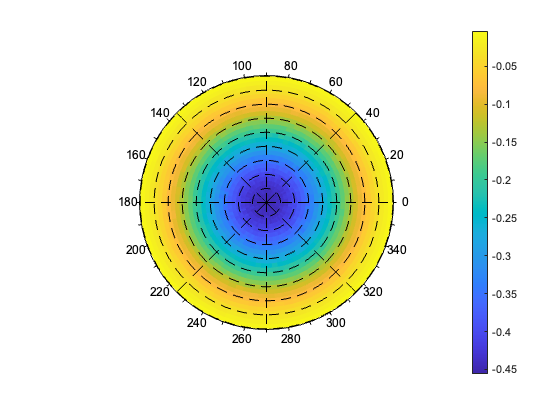


figure
polarplot3d(srpCsTrueZ, 'GridStyle', '--', 'PolarGrid', {9 8}, 'PlotType', 'surfn');
view([0 90]); axis equal
clim(czRange)

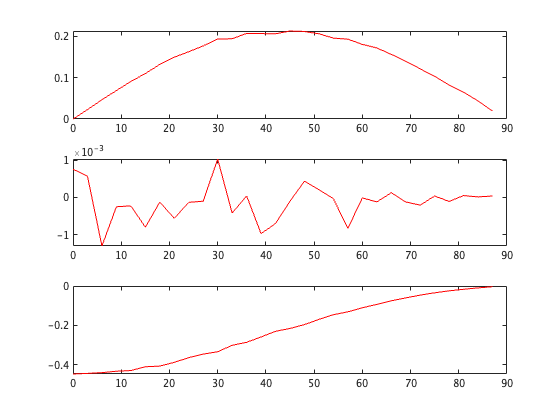


figure
tiledlayout(3,1), nexttile
plot(rad2deg(thetaI(:,1)), srpCsTrueX(:,1),'r'), hold on
% ylim([-3e-6 0])
nexttile
plot(rad2deg(thetaI(:,1)), srpCsTrueY(:,1),'r'), hold on
% ylim([-3e-6 0])
nexttile
plot(rad2deg(thetaI(:,1)), srpCsTrueZ(:,1),'r'), hold on

% ylim([-3e-6 0])